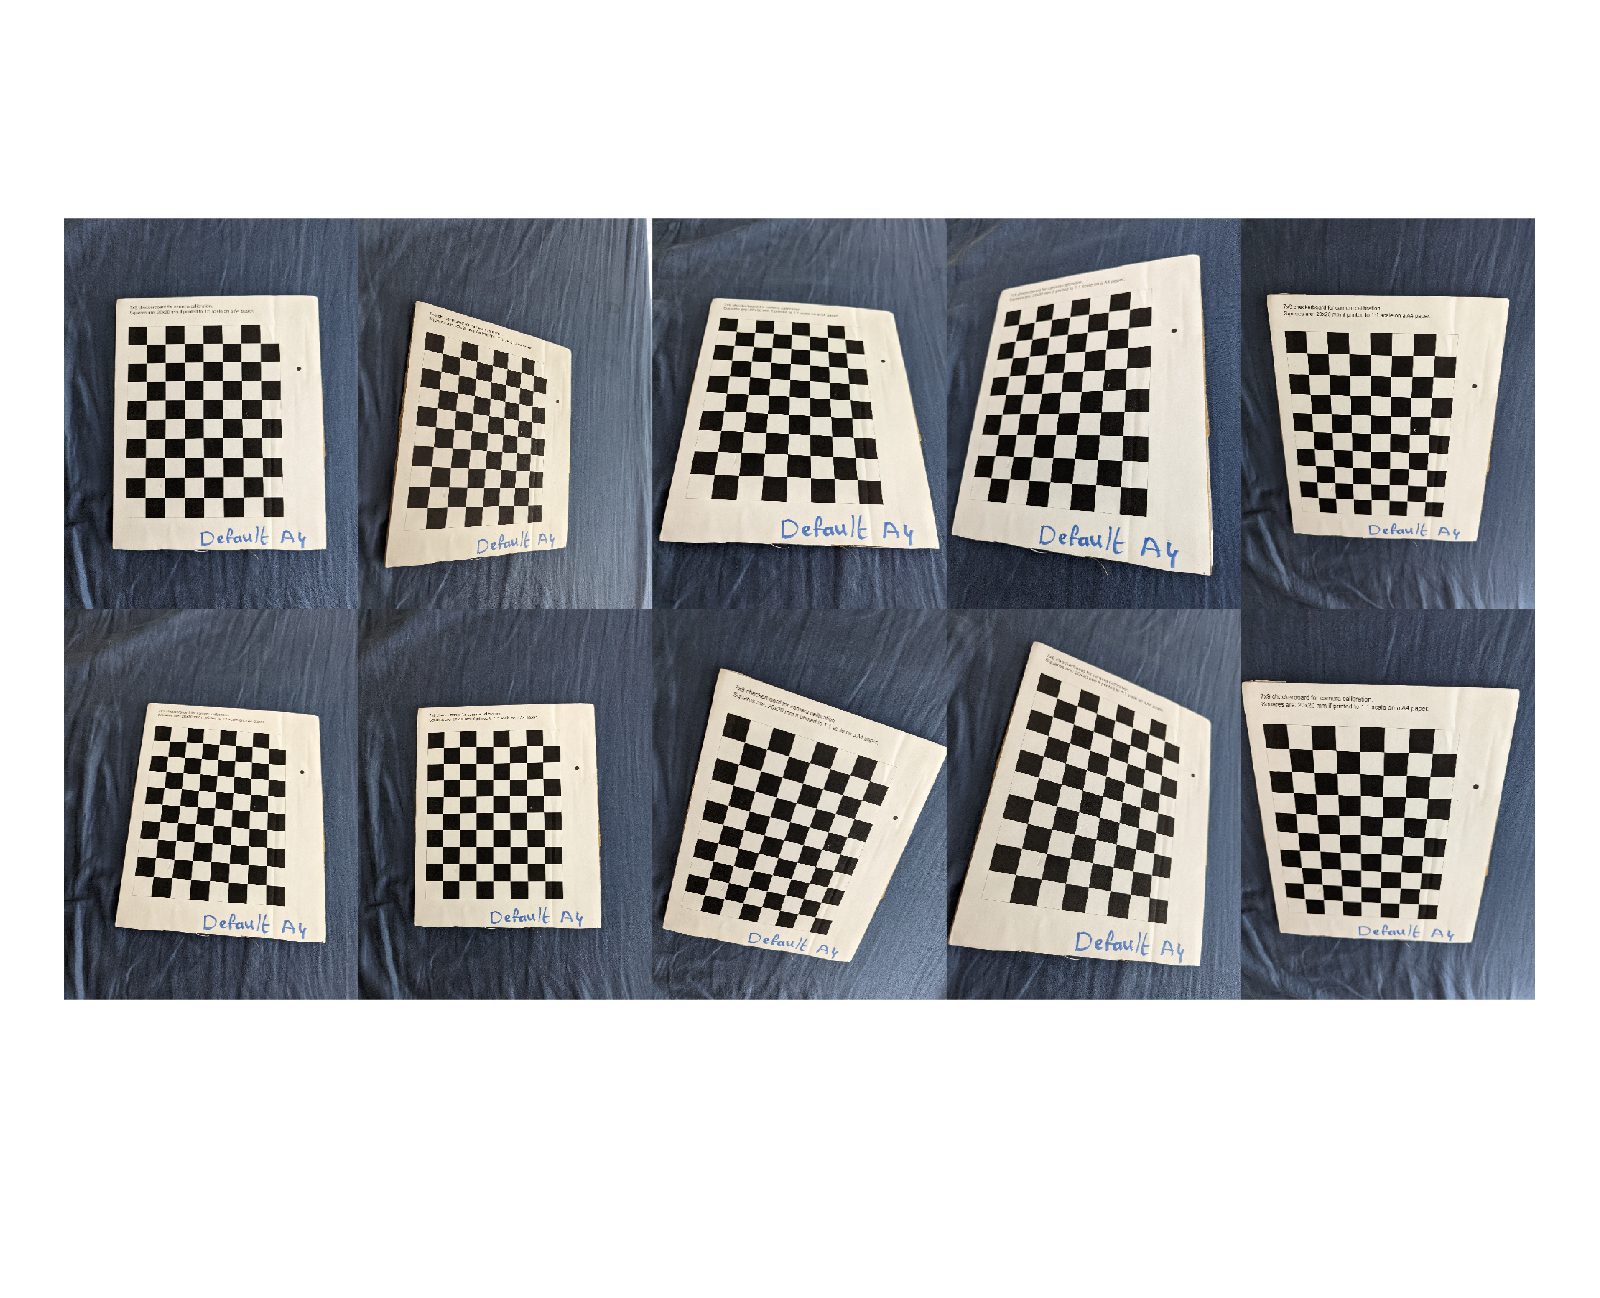

% Folder in which checker board images exist
imagesLocation = '/Users/sathwikchowda/Desktop/Checkerboard/*jpg';
images = imageDatastore(imagesLocation);
montage(images,'Size',[2 5])

% Detect calibration pattern in images
detector = vision.calibration.monocular.CheckerboardDetector();
[imagePoints, imagesUsed] = detectPatternPoints(detector, images.Files);

% Read the first image to obtain image size
disp(images.Files)

    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_191917848.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_191922686.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_191925856.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_191931141.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_191935639.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_191955055.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_191957592.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_192004205.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_192018843.jpg'}
    {'/Users/sathwikchowda/Desktop/Checkerboard/PXL_20220430_192039949.jpg'}



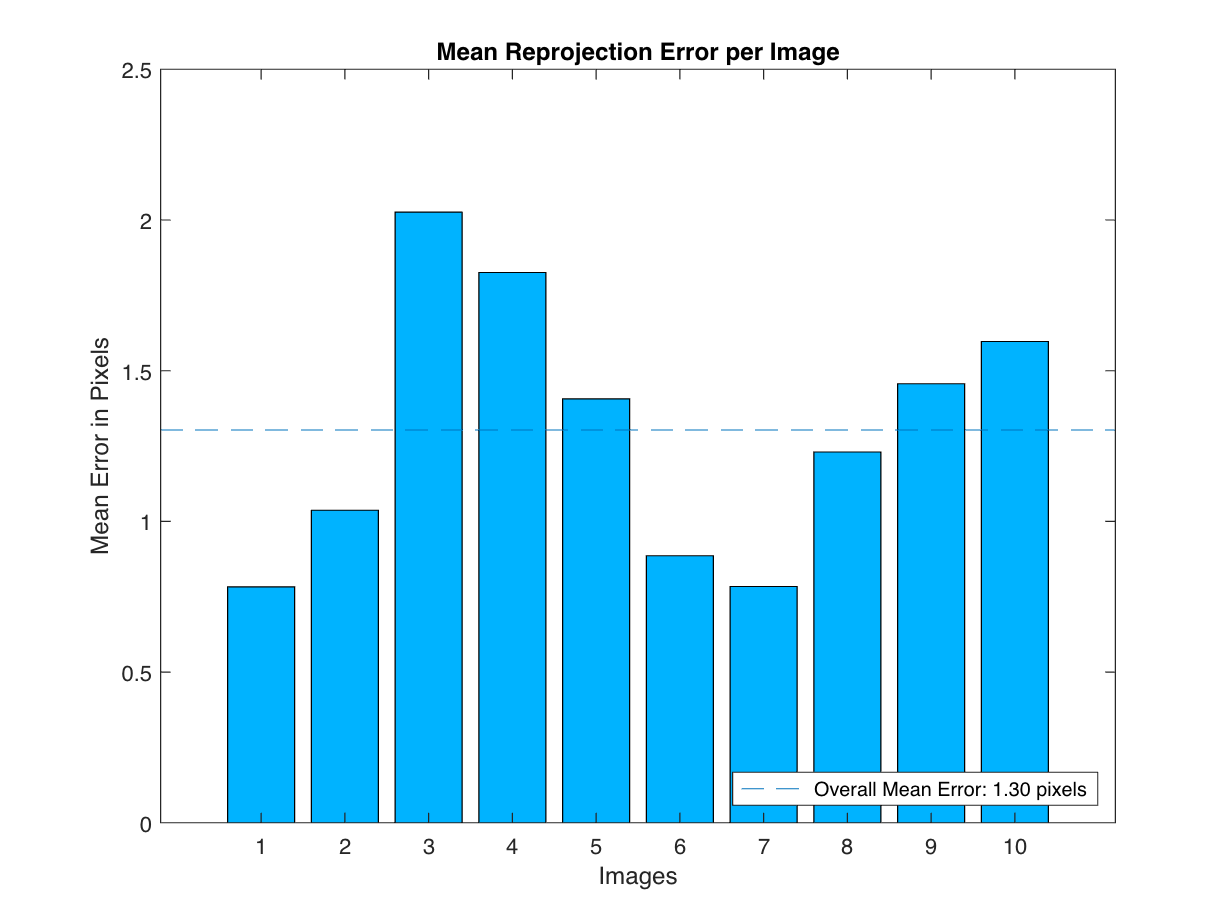

originalImage = imread(images.Files{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates for the planar pattern keypoints
squareSize = 25;  % in units of 'millimeters'
worldPoints = generateWorldPoints(detector, 'SquareSize', squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);

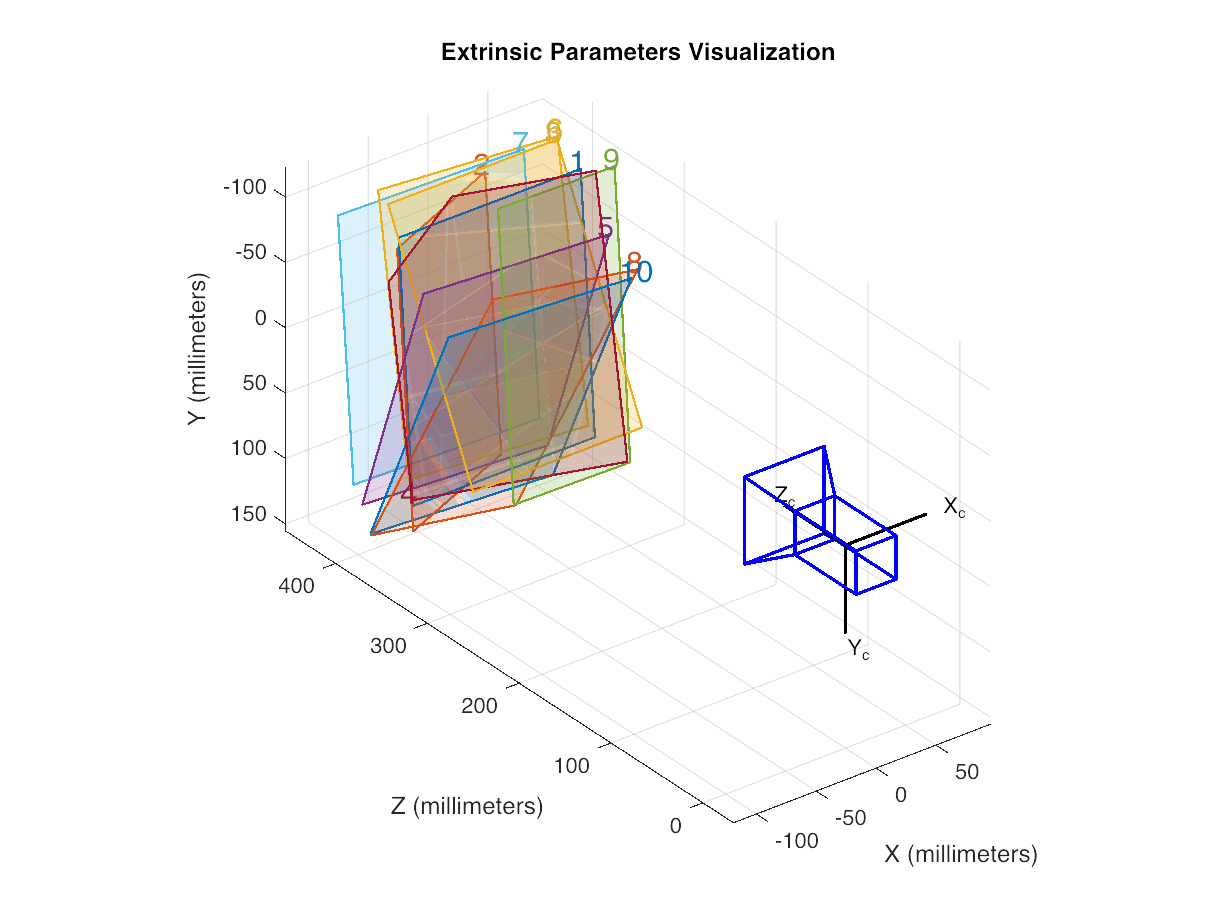


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 2960.4504 +/- 5.2759     2949.9739 +/- 5.4568  ]
Principal point (pixels):[ 1527.0197 +/- 2.4015     2043.0641 +/- 2.1086  ]
Radial distortion:       [    0.0691 +/- 0.0062       -0.4041 +/- 0.0320  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0392 +/- 0.0017        0.0682 +/- 0.0017        1.5629 +/- 0.0002  ]
                         [   -0.5295 +/- 0.0014       -0.2963 +/- 0.0013        1.6302 +/- 0.0003  ]
                         [   -0.4592 +/- 0.0011        0.3266 +/- 0.0010        1.5682 +/- 0.0003  ]
                         [   -0.4929 +/- 0.0010        0.0332 +/- 0.0009       -1.5084 +/- 0.0003  ]
                         [    0.2928 +/- 0.0012       -0.2152 +/- 0.0012        1.5756 +/- 0.0003  ]
                         [   -0.2156 +/- 0.0017        0.2039 +/- 0.0016        1.6350 +/- 0.0003  ]
 


% For example, you can use the calibration data to remove effects of lens distortion.
undistortedImage = undistortImage(originalImage, cameraParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('MeasuringPlanarObjectsExample')
% showdemo('StructureFromMotionExample')
